clear all;
data_full = readmatrix("FCC-256\thermo_liquido.csv");
data = data_full(1000:end,5);
n_dati = length(data);

varianze = [];
numero_blocchi = [];

jj = 1;

for N_BLOCCHI = 1:5:n_dati
    scarto = mod(n_dati,N_BLOCCHI); 
    dati_tmp = data(1:end-scarto);
    medie_blocchi = zeros(1,N_BLOCCHI);
    dati_blocco = (n_dati-scarto)/N_BLOCCHI;
    for kk = 1:N_BLOCCHI
        blocco = dati_tmp(((kk-1)*dati_blocco)+1:(kk*dati_blocco));
        media_blocco = mean(blocco);
        medie_blocchi(kk) = media_blocco;
    end
    numero_blocchi(jj) = N_BLOCCHI;
    varianze(jj) = var(medie_blocchi) / N_BLOCCHI;
    jj = jj+1;
end

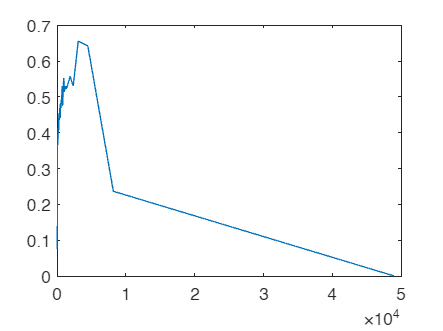

figure();
plot(n_dati./numero_blocchi,sqrt(varianze));

plateau = 0.019;
varianza = var(data);
tau = (plateau^2)*n_dati/varianza - 1

tau = -0.9344

x = flip((n_dati./numero_blocchi));
y = flip(sqrt(varianze));

fit = functionFit();
fit.showRes = 0;
fit.showChi = 0;
fit.title = "Plateau energia liquido FCC-256";
fit.datax = x(7000:end-5);
fit.datay = y(7000:end-5);
fit.model = @(par,x) (1-par(3)*exp(-x/par(1)))*par(2);
fit.parnames = ["\tau", "\sigma_0", "B"];
fit.par = [3,0.025,3];
fit.labelx = "# particelle blocco";
fit.labely = "\sigma_{blocco}"

fit =   functionFit with properties:

                  datax: [2797×1 double]
                  datay: [2797×1 double]
                 sigmax: [0×1 double]
                 sigmay: [0×1 double]
                  model: @(par,x)(1-par(3)*exp(-x/par(1)))*par(2)
                    par: [3×1 double]
                 errpar: [0×1 double]
            previousPar: [0×1 double]
            upperBounds: [0×1 double]
            lowerBounds: [0×1 double]
                  units: [0×1 string]
               parnames: [3×1 string]
         noOversampling: 0
                   yfit: [0×1 double]
               chi2norm: Inf
                    fig: 0
                   axes: [0×1 double]
                    dof: 0
                 pValue: 0
           showParArray: [2×1 logical]
                showChi: 0
            showChiNorm: 0
             showPValue: 0
                showBox: 1
                showRes: 0
               sh


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


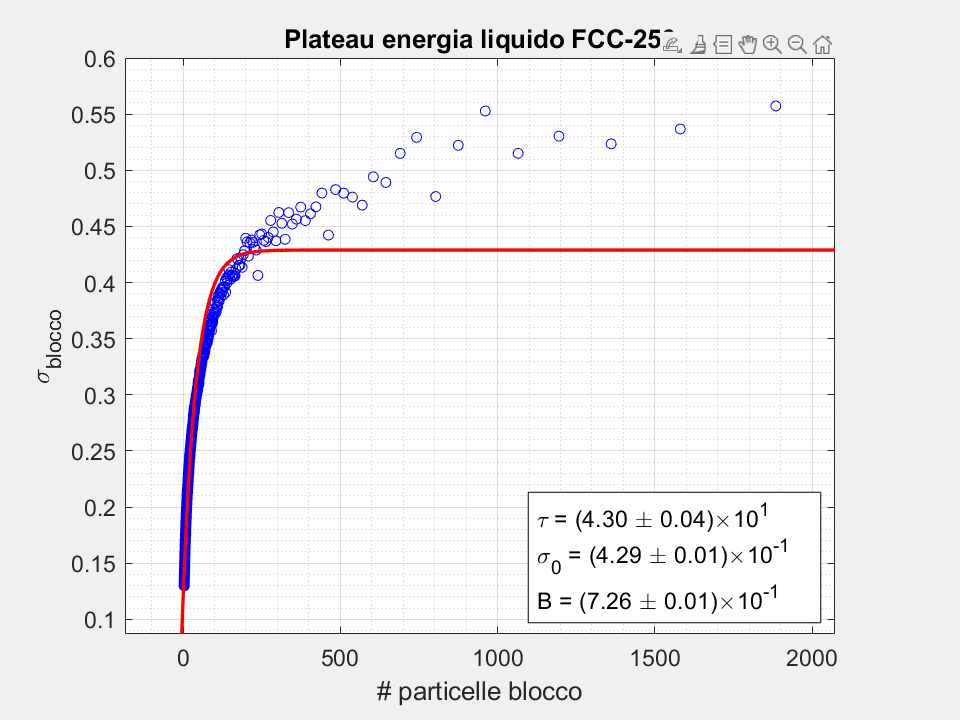

fit.boxPosition = "southeast";
fit.plotModelFit("plateau_energia_liquido");